## Ejercicio 1

clc; clear; close all

Gs = tf([32], conv([1 0], conv([0.1 1], [1 1])))


Gs =
 
           32
  ---------------------
  0.1 s^3 + 1.1 s^2 + s
 
Continuous-time transfer function.



Kv = 4;
Kc = Kv/32

Kc = 0.1250


Pmd = 45;
Pm = 17.7; % margen sin compensar aprox
comp = 14; % compensacion extra

phim = deg2rad(Pmd - Pm + comp);
beta = (1 - sin(phim))/(1 + sin(phim))

beta = 0.2048


omega = 2.8316;

beta1 = omega*sqrt(beta)

beta1 = 1.2815

beta2 = omega/sqrt(beta)

beta2 = 6.2567


Gc_1 = (Kc/beta)*tf([1 beta1], [1 beta2])


Gc_1 =
 
  0.6103 s + 0.7821
  -----------------
      s + 6.257
 
Continuous-time transfer function.


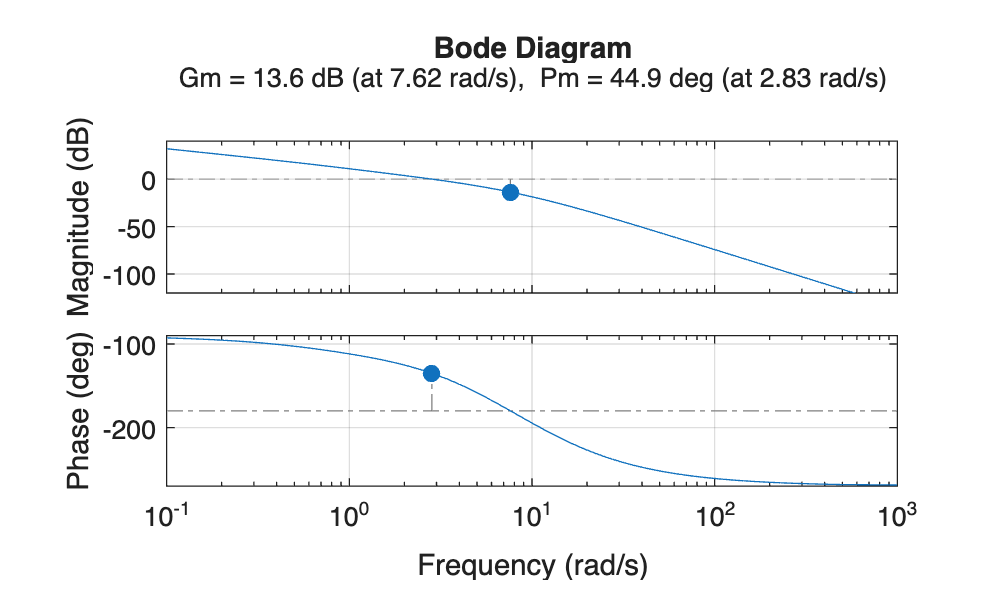


figure(1)
margin(Gc_1*Gs)
grid on

## Ejercicio 2

Gs = tf([2 0.1], [1 0.1 4])


Gs =
 
     2 s + 0.1
  ---------------
  s^2 + 0.1 s + 4
 
Continuous-time transfer function.



Cp = 4;
Kc = Cp/dcgain(Gs)

Kc = 160


alpha = 5;

alpha1 = 177; % cero
alpha2 = alpha1/alpha; % polo

Gc_2 = (Kc/alpha)*tf([1 alpha1], [1 alpha2])


Gc_2 =
 
  32 s + 5664
  -----------
   s + 35.4
 
Continuous-time transfer function.


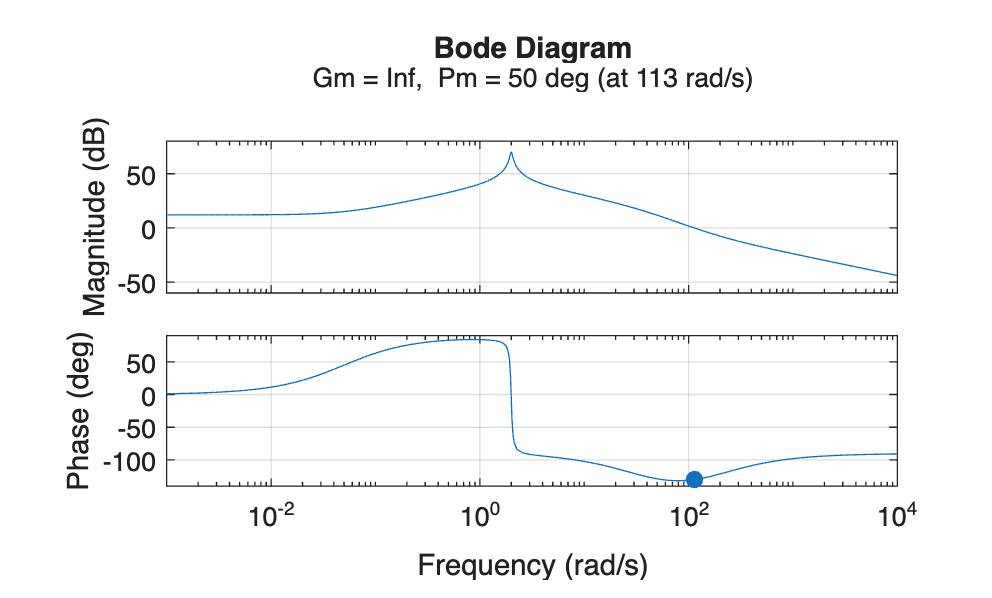


figure(2)
margin(Gc_2*Gs)
grid on

## Ejercicio 3

Gs = tf([1], conv([1 0], conv([1 1], [1 5])))


Gs =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.



Cv = 20;
Kc = Cv/(1/5)

Kc = 100


Pmd = 60;
comp = 1;

omega = sqrt(5);

phim = deg2rad(Pmd + comp);
gamma = (1 + sin(phim))/(1 - sin(phim))

gamma = 14.9515


alpha1 = omega/10

alpha1 = 0.2236

alpha2 = omega/(10*gamma)

alpha2 = 0.0150


beta1 = omega/sqrt(gamma)

beta1 = 0.5783

beta2 = omega*sqrt(gamma)

beta2 = 8.6462


Gc_3 = Kc*tf(conv([1 alpha1], [1 beta1]), conv([1 alpha2], [1 beta2]))


Gc_3 =
 
  100 s^2 + 80.19 s + 12.93
  -------------------------
   s^2 + 8.661 s + 0.1293
 
Continuous-time transfer function.


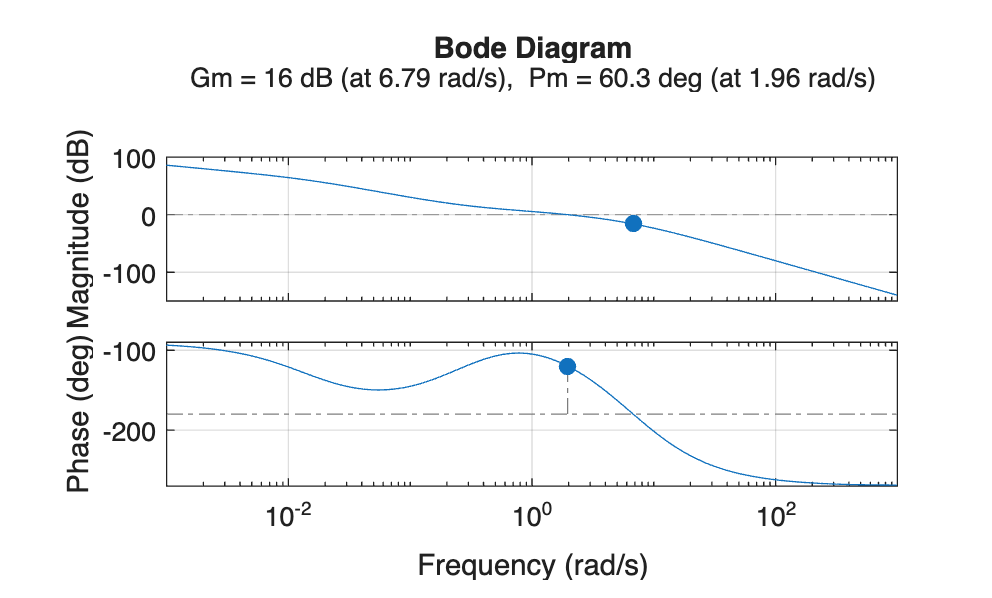


figure(3)
margin(Gc_3*Gs)
grid on